# Practice Using Bag of Features

In the "Classifying Images Using Bag of Features" video, you saw how optional parameters to the `bagOfFeatures` function can affect how predictor features are generated. 

In this reading, you’ll investigate the effect of `"GridStep"` size on the time it takes to create a bag and the classification results for the concrete images.

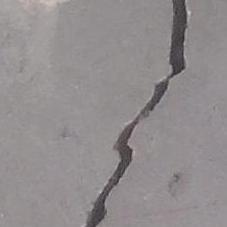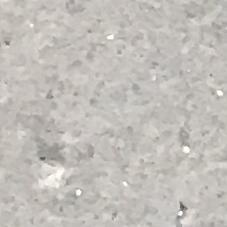

`"GridStep"` is just one important parameter that affects the extracted features. Others include:

- Point Selection Method

- Block Width

- Custom Detection Functions

After this reading, feel free to experiment with different `bagOfFeatures` parameters and observe their effect on the resulting trained models.

## Preparing the Data

Perform the same steps that you performed in the "Preparing Your Images for Classification" live script reading to create a labeled data set and split it into training and testing sets.

Make sure that you navigate to the "Concrete" subfolder in the "Data" folder of the course download.

filePath = uigetdir;
dsConcrete = imageDatastore(filePath,"IncludeSubFolders",true,...
    "LabelSource","foldernames");
dsConcrete.Labels = renamecats(dsConcrete.Labels,["No Crack" "Crack"]);
[dsTrain,dsTest] = splitEachLabel(dsConcrete,0.8,"randomize");

Machine learning is a computationally intensive process. Because generating predictor features using bag of features can take some time, for this reading you have the option to use a smaller subsample of 100 images.

If you instead wish to run code with the full training set of 800 images, choose the "Full Data Set" option:

if 1
    nFiles = length(dsTrain.Files);
    randIdxs = randperm(nFiles);
    randIdxs = randIdxs(1:100);
    dsTrain = subset(dsTrain,randIdxs);
end

## Generating Predictor Features with BagOfFeatures

### Default Features

First, create a feature bag using the default `bagOfFeatures` options. Even with a smaller training data set, this may take a few minutes to run.

Each call to `bagOfFeatures` is surrounded by `tic` and `toc` commands. This will output the time, in seconds, that it took to execute the enclosed code, allowing you to compare run times with different `bagOfFeatures` parameters. 

tic
bag = bagOfFeatures(dsTrain);


Creating Bag-Of-Features.
-------------------------
* Image category 1: No Crack
* Image category 2: Crack
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 100 images...done. Extracted 313600 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 2 has the least number of strongest features: 110387.
** Using the strongest 110387 features from each of the other image categories.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 220774
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clustering...completed 52/100 itera

T = toc

T = 32.9419


predFeats = encode(bag,dsTrain);


Encoding images using Bag-Of-Features.
--------------------------------------
* Image category 1: No Crack
* Image category 2: Crack
* Encoding 100 images...done.


featNames = "f" + string(1:500);
predTable = array2table(predFeats,"VariableNames",featNames);
predTable.labels = categorical(dsTrain.Labels);

Go to the Classification Learner app and use these predictor features to train a cubic SVM model. You will compare these results to those of a model created using a bag with a different grid step size.

### Grid Step Size

Create feature bags with a different grid step size here:

% Create feature bag using "Grid" point selection with a grid step size of
% 32 pixels
tic
bagGridLarge = bagOfFeatures(dsTrain,"GridStep",[32 32]);


Creating Bag-Of-Features.
-------------------------
* Image category 1: No Crack
* Image category 2: Crack
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [32 32] and the BlockWidth is [32 64 96 128].

* Extracting features from 100 images...done. Extracted 19600 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 2 has the least number of strongest features: 6899.
** Using the strongest 6899 features from each of the other image categories.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 13798
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clustering...completed 24/100 iteration

TGL = toc

TGL = 3.1666


% Prepare predictor features for training
predFeatsGridLarge = encode(bagGridLarge,dsTrain);


Encoding images using Bag-Of-Features.
--------------------------------------
* Image category 1: No Crack
* Image category 2: Crack
* Encoding 100 images...done.


% Label feature variables, one per visual word
featNames = "f" + string(1:size(predFeatsGridLarge,2));
% Convert to labeled table
predTableGridLarge = array2table(predFeatsGridLarge,"VariableNames",featNames);
predTableGridLarge.labels = categorical(dsTrain.Labels);

The concrete images are 227x227 pixels. By comparing the results of the models trained using different grid step sizes, you can determine how many feature descriptors are required to sufficiently describe the images.

Train a cubic SVM model in the classification learner app using these features and compare it to that of the model trained with default `bagOfFeatures` parameters.

## Train and Compare Models

Given several trained models, the following code creates a table that compares the validation accuracies and run times for different models created using different `bagOfFeatures` parameters.

Use this table as a template to compare different trained models in the future. It will help you find a tradeoff between speed and accuracy that works well for your applications.

validationAccuracy = 97;
validationAccuracyGL = 95;

table([validationAccuracy; validationAccuracyGL],...
    [T; TGL],...
    'VariableNames',{'Accuracy','Run Time (s)'},...
    'RowNames',{'Default','Grid Small'})

ans = 2×2 table
                  Accuracy    Run Time (s)
                  ________    ____________

    Default          97          32.942   
    Grid Small       95          3.1666   


*Copyright 2022 The MathWorks, Inc.*